# TCLab Higher Order Models

**Objective**: Simulate a third-order transfer function, state space, and fifth-order time series model of $T_{C2}$ temperature response to heater $Q_1$.

Higher-order models are better at predicting system dynamics for complex systems. This exercise is to create a third-order transfer function, state space, and a fifth-order time series model as linear representations of step response data. If heater 1 ($Q_1$) controls temperature 2 ($T_{C2}$), the generated heat first raises the heater 1 temperature ($T_{H1}$). The heat is transferred by convection to heater 2 ($T_{H2}$) and finally reaches temperature 2 sensor ($T_{C2}$) by conduction. This heat transfer pathway suggests a third-order dynamic model, although a higher-order model may improve the fit even further.

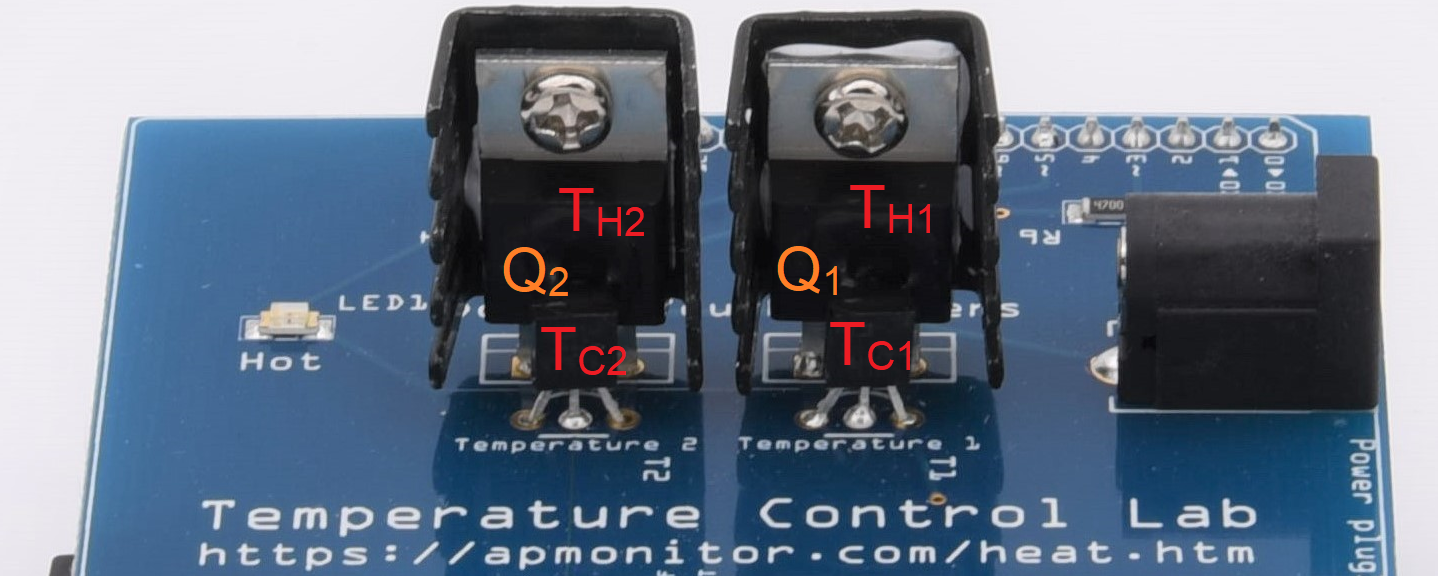

## **Estimate Parameters Using a Physics Based Model and **`Python GEKKO`

A physics-based model is developed in prior exercises as a second-order system. The second-order physics-based model consists of four differential equations from energy balances that include convection, conduction, and thermal radiation. There are three differential equations when considering the heat pathway from heater 1 ($Q_1
$) to temperature 2 sensor ($T_{C2}
$).


$$m\,c_p\frac{dT_{H1}}{dt} = U\,A\,\left(T_\infty-T_{H1}\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_{H1}^4\right) + Q_{C12} + Q_{R12} + \alpha_1 Q_1$$



$$m\,c_p\frac{dT_{H2}}{dt} = U\,A\,\left(T_\infty-T_{H2}\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_{H2}^4\right) - Q_{C12} - Q_{R12} + \alpha_2 Q_2$$



$$\tau \frac{dT_{C2}}{dt} = T_{H2} - T_{C2}

$$


with the following heat transfer terms for simplifying the expressions.


$$Q_{C12} = U_s \, A_s \, \left(T_{H2}-T_{H1}\right)$$



$$Q_{R12} = \epsilon\,\sigma\,A_s\,\left(T_{H2}^4-T_{H1}^4\right)$$



$$\tau = \frac{m_s \, c_{p,s} \, \Delta x}{k\,A_c}$$



$$\matrix{

\textbf{Component} & \textbf{Value}\cr
\text{Initial Temperature}(T_0) & 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Ambient Temperature}(T_\infty)& 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Heater 1 Output}(Q_1) & 0-100\%\cr
\text{Heater 1 Factor}(\alpha_1) & 0.0123 \text{ W/(\% heater)}\cr
\text{Heater 2 Output}(Q_2) & 0-100\%\cr
\text{Heater 2 Factor}(\alpha_2) & 0.0062 \text{ W/(\% heater)}\cr
\text{Heat Capacity}(C_p) & 500 \text{ J/kg-K}\cr
\text{Surface Area Not Between Heaters}(A) & 1.0*10^{-3}\text{ m}^2(10\text{ cm})\cr
\text{Surface Area Between Heaters}(A_s) & 2.0*10^{-4}\text{ m}^2(2\text{ cm})\cr
\text{Mass}(m) & 0.004\text{ kg }(4 \text{ gm })\cr
\text{Conduction Time Constant}(\tau) & 20.3 \text{ sec}\cr
\text{Overall Heat Transfer Coefficient} (U) & 4.7 \text{ W/m}^2\text{-K}\cr
\text{Overall Heat Transfer Coefficient Between Heaters}(U_s) & 15.45 \text{ W/m}^2\text{-K}\cr
\text{Emissivity}(\epsilon) & 0.9\cr
\text{Stefan Boltzmann Constant }(\sigma) & 5.67*10^{-8} \text{ W/m}^2\text{-K}^4\cr
}$$


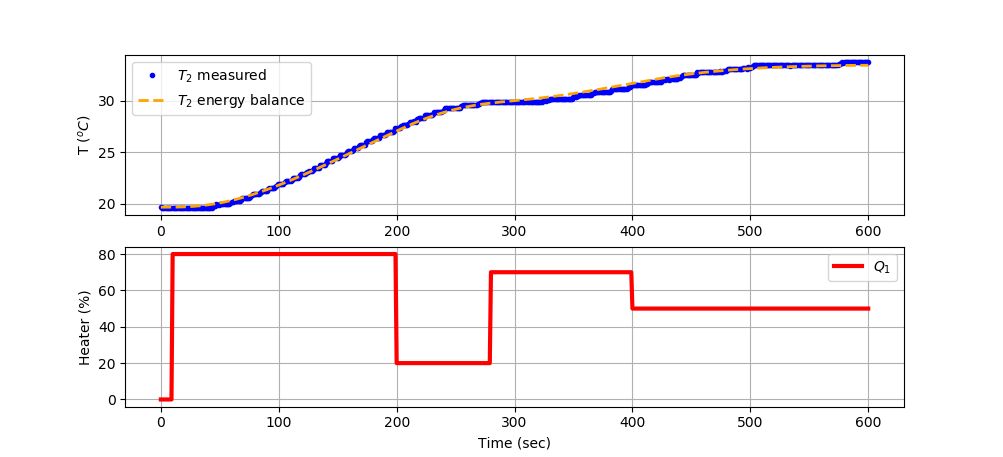

Perform tclab stepchange or read from file

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);
% Collect data

filename = "Step_Response.csv";
absolute_path = fullfile(directory, filename);

try % try to read from file first
    A = readmatrix(absolute_path)
    tm_ = A(:,1);
    T1_ = A(:,2);
    T2_ = A(:,3);
    Q1_ = A(:,4);
    Q2_ = A(:,5);
    disp('TCLab Data read from file')
    
    figure()
    hold on
    subplot(2,1,1)
    plot(tm_, T1_, 'r.', 'DisplayName','T1')
    hold on
    plot(tm_, T2_, 'b.', 'DisplayName','T2')
    hold off
    legend('Location',"best")
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_, Q1_, 'r-','DisplayName','Q1')
    hold on
    plot(tm_, Q2_, 'b-','DisplayName','Q2')
    hold off
    xlabel('Time (sec)')
    ylabel('Heater Setting (%)')
    legend('Location',"best")
    
catch % if file can not be found, simulate
    try 
        lab = tclab;

        n = 600;
        tm_ = zeros(n+1, 1);
        Q1_ = zeros(n+1, 1);
        Q1_(10:200) = 80;
        Q1_(200:280) = 20;
        Q1_(280:400) = 70;
        Q1_(400:end) = 50;
        
        Q2_ = zeros(n+1, 1);
        T1_ = ones(n+1, 1) * lab,T1;
        T2_ = ones(n+1, 1) * lab.T1;
        % initialize lab
        
        tic;
        figure()
        hold on
        for i=2:n+1
            pause(1-mod(toc,1));
            tm_(i) = toc;
            T1_(i) = lab.T1;
            T2_(i) = lab.T2;
            lab.Q1(Q1_(i));
            lab.Q2(Q2_(i));
            
        
            subplot(2,1,1)
            plot(tm_(1:i), T1_(1:i), 'r.',tm_(1:i), T2_(1:i), 'b.')
            legend({'T1' 'T2'}, 'Location',"best")
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm_(1:i), Q1_(1:i), 'r-',tm_(1:i), Q2_(1:i), 'b-')
            xlabel('Time (sec)')
            ylabel('Heater Setting (%)')
            legend({'Q1' 'Q2'}, 'Location',"best")
            
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm_, T1_, T2_, Q1_, Q2_]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

viewSolution(false)

use fmincon to perform constrained optimization with bounds. fmincon requires the optimization toolbox. Inequality constraints are passed as Ax<=b. To create a lower bound, we use -x <= -b for any given lower bound.

% create initial guesses and max/min constraints
% [U, Us, alpha1, alpha2, tau]



## Simulate State Space Model

Below is a derivation of the state space and transfer function model of temperature 2 sensor response to heater 1 changes.


$$\left[ \matrix{\dot T'_{H1} \cr \dot T'_{H2} \cr \dot{T}'_{C2} }  \right]=
\left[ \matrix{a_{1,1} & a_{1,2} & a_{1,3} \cr a_{2,1} & a_{2,2} & a_{2,3} \cr a_{3,1} & a_{3,2} & a_{3,3}} \right]
\left[ \matrix{T'_{H1} \cr T'_{H2}\cr T'_{C2}}\right] +
\left[ \matrix{b_{1,1}\cr b_{2,1}\cr b_{3,1}} \right]
\left[ \matrix{Q'_1} \right]$$



$$\left[ \matrix{ \dot{T}'_{C2} }  \right]=
\left[ \matrix{0 & 0 & 1} \right]
\left[ \matrix{T'_{H1} \cr T'_{H2}\cr T'_{C2}}\right] +
\left[ \matrix{0} \right]
\left[ \matrix{Q'_1} \right]$$


In State Space Form:


$$\dot{x}=Ax+Bu \\
y=Cx+Du$$


The individual elements are obtained by evaluating partial derivatives of the differential equations at steady state conditions.


$$a_{1,1} = \frac{\partial f_1}{\partial T_{H1}}\bigg|_{\bar Q,\bar T} = -\frac{U\,A + 4 \epsilon \sigma A T_0^3 + U_s \, A_s + 4 \epsilon \sigma A_s T_0^3}{m\,C_p} = -0.00698$$



$$a_{1,2} = \frac{\partial f_1}{\partial T_{H2}}\bigg|_{\bar Q,\bar T} = \frac{U_s \, A_s + 4 \epsilon \sigma A_s T_0^3}{m\,C_p} = 0.00206$$



$$a_{2,1} = \frac{\partial f_2}{\partial T_{H1}}\bigg|_{\bar Q,\bar T} = \frac{U_s \, A_s + 4 \epsilon \sigma A_s T_0^3}{m\,C_p} = 0.00206$$



$$a_{2,2} = \frac{\partial f_2}{\partial T_{H2}}\bigg|_{\bar Q,\bar T} = -\frac{U\,A + 4 \epsilon \sigma A T_0^3 + U_s \, A_s + 4 \epsilon \sigma A_s T_0^3}{m\,C_p} = -0.00698$$



$$a_{3,2} = \frac{\partial f_3}{\partial T_{H2}}\bigg|_{\bar Q,\bar T} = \frac{1}{\tau} = 0.0493$$



$$a_{3,3} = \frac{\partial f_3}{\partial T_{C2}}\bigg|_{\bar Q,\bar T} = -\frac{1}{\tau} = -0.0493$$



$$b_{1,1} = \frac{\partial f_1}{\partial Q_1}\bigg|_{\bar Q,\bar T} = \frac{\alpha_1}{m\,C_p} = 0.00616$$


The state space model has four matrices with $A$ and $B$ that are obtained from the partial derivatives of the right hand side of the differential equations.


$$A \in \mathbb{R}^{3 \, \mathrm{x} \, 3} =
 \left[ \matrix{a_{1,1} & a_{1,2} & a_{1,3}\cr a_{2,1} & a_{2,2} & a_{2,3} \cr a_{3,1} & a_{3,2} & a_{3,3}} \right]  =
\left[ \matrix{-0.00698 & 0.00206 & 0\cr 0.00206 & -0.00698 & 0\cr 0 & 0.0493 & -0.0493} \right]$$



$$B \in \mathbb{R}^{3 \, \mathrm{x} \, 1} = \left[ \matrix{0.00616\cr 0\cr 0}\right]$$



$$C \in \mathbb{R}^{1 \, \mathrm{x} \, 3} = \left[ \matrix{0 & 0 & 1} \right]$$



$$D \in \mathbb{R}^{1 \, \mathrm{x} \, 1} = \left[0\right]}$$


viewSolution2(false)

Create an empirical state space model from the regressed parameters earlier in this activity and the above equations for elements of $A$and $B$.

Ta =20.0+273.15;                     % K
mass = 4.0/1000.0;                   % kg
Cp = 0.5*1000.0;                     % J/kg-K    
A = 10.0/100.0^2;                    % Area not between heaters in m^2
As = 2.0/100.0^2;                    % Area between heaters in m^2
eps = 0.9;                           % Emissivity
sigma = 5.67e-8;                     % Stefan-Boltzmann

a11 =  ; % -(U * A + 4*eps * sigma * A * Ta^3 + Us*As + 4*eps * sigma * As * Ta^3) / (mass * Cp)
a12 =  ; % (Us * As + 4*eps*sigma*As*Ta^3)/(mass*Cp)
a21 =  ;
a22 =  ;
a32 =  ;
a33 =  ;
b11 =  ;

A = [a11, a12, 0;...
    a21, a22, 0;...
    0, a32, a33]
B = [b11; 0; 0]

 Matricies $C$ and $D$ should not change and are provided.

C = [0, 0, 1];
D = [0];

sys = ss(A, B, C, D);
u = [Q1_]
Ta = 23.0
x0 = [Ta; Ta; Ta; Ta]
t = linspace(0, max(tm_), 601)
y = lsim(sys, u, t)

Plot the Simulated State Space Model Compared to the TCLab Data

T1_SS = y(:,1) + T1_(2)
T2_SS = y(:,2) + T2_(2)

figure()
hold on
subplot(2,1,1)
plot(tm_, T1_, 'r.', 'DisplayName','T1')
hold on
plot(tm_, T2_, 'b.', 'DisplayName','T2')
hold on
plot(t, T1_SS, 'r-', 'DisplayName','T1 Predicted')
hold on
plot(t, T2_SS, 'b-', 'DisplayName','T2 Predicted')
hold off
legend('Location',"best")
ylabel('Temperature (C)')
subplot(2,1,2)
plot(tm_, Q1_, 'r-','DisplayName','Q1')
hold on
plot(tm_, Q2_, 'b-','DisplayName','Q2')
hold off
xlabel('Time (sec)')
ylabel('Heater Setting (%)')
legend('Location',"best")


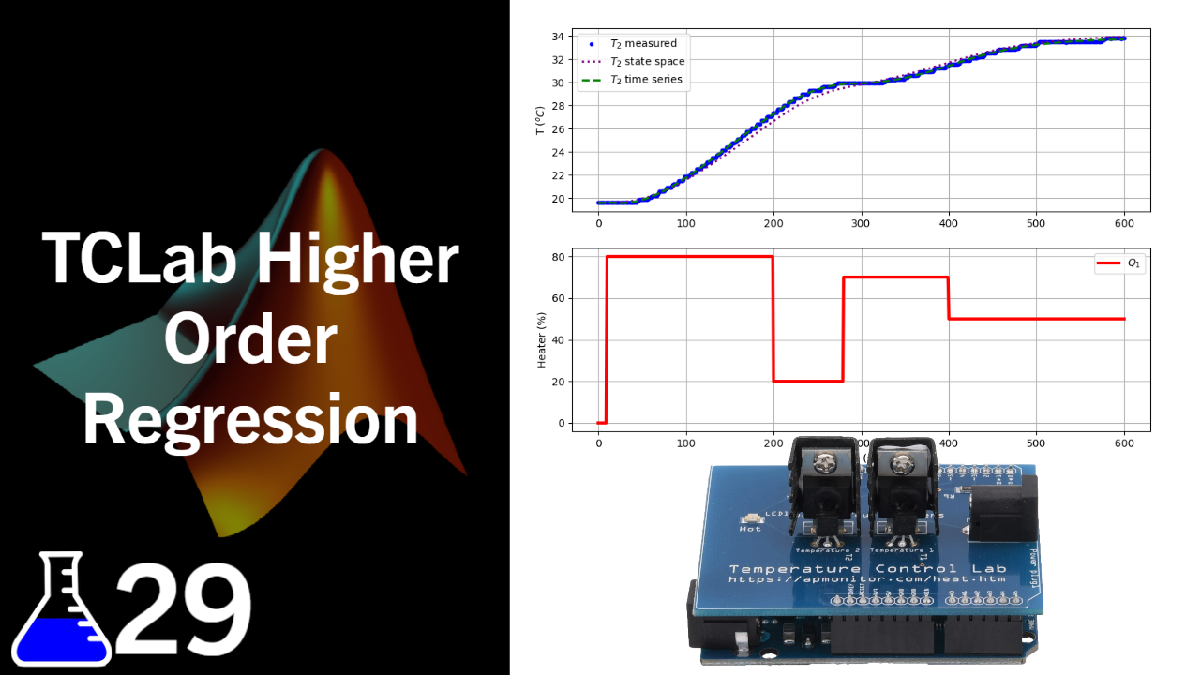

### [View Solution](https://youtu.be/Fo24VCpALAk)

function dTdt = model(~  ,T,  Q1, Q2, params)
    % unpack states
    TH1 = T(1);
    TH2 = T(2);
    TC1 = T(3);
    TC2 = T(4);
    
    % Unpack Regressed Constants
    U = params(1);
    Us = params(2);
    alpha1 = params(3);
    alpha2 = params(4);
    tau = params(5);
    
    % Constants
    Ta =20.0+273.15;                     % K
    mass = 4.0/1000.0;                   % kg
    Cp = 0.5*1000.0;                     % J/kg-K    
    A = 10.0/100.0^2;                    % Area not between heaters in m^2
    As = 2.0/100.0^2;                    % Area between heaters in m^2
    eps = 0.9;                           % Emissivity
    sigma = 5.67e-8;                     % Stefan-Boltzmann
    
    % Heater Temperatures in Kelvin
    T1 = TH1 + 273.15;
    T2 = TH2 + 273.15;
    
    % Heat transfer between two heaters
    Q_C12 = Us*As*(T2-T1);  % Convective
    Q_R12 = eps*sigma*As*(T2^4-T1^4);  % Radiative
    
    % Calculate derivative values
    TH1dt = (1.0/(mass*Cp))*(U*A*(Ta-T1) ...
                + eps * sigma * A * (Ta^4 - T1^4) ...
                + Q_C12 + Q_R12 ...
                + alpha1*Q1);
    TH2dt = (1.0/(mass*Cp))*(U*A*(Ta-T2) ...
                + eps * sigma * A * (Ta^4 - T2^4) ...
                - Q_C12 - Q_R12 ...
                + alpha2*Q2);
    TC1dt = (TH1 - TC1)/tau;
    TC2dt = (TH2 - TC2)/tau;
    
    dTdt = [TH1dt; TH2dt; TC1dt; TC2dt];
end

function T_ = simModel(T0, tm_, Q1_, Q2_, params)
    n = length(tm_);
    TH1sim_ = ones(n, 1) * T0(1);
    TH2sim_ = ones(n, 1) * T0(2);
    TC1sim_ = ones(n, 1) * T0(1);
    TC2sim_ = ones(n, 1) * T0(2);
    
    T0 = [TH1sim_(1); TH2sim_(1); TC1sim_(1); TC2sim_(1)];
    for i=1:n-1
        ts = [tm_(i) tm_(i+1)];
        [~,T] = ode45(@( t,T) model(t,T,  Q1_(i), Q2_(i), params), ts, T0);
        T0 = T(end,:);
        TH1sim_(i+1) = T0(1);
        TH2sim_(i+1) = T0(2);
        TC1sim_(i+1) = T0(3);
        TC2sim_(i+1) = T0(4);
    end
    T_ = [TH1sim_, TH2sim_];
end

function sse = objective(params, tm_, Q1_, Q2_, T1m_, T2m_)
    Tsim = simModel([T1m_(2), T2m_(2)], tm_, Q1_, Q2_, params);
    
    sse = sum((Tsim(:,1) - T1m_).^2) + sum((Tsim(:,2) - T2m_).^2);
end

function viewSolution(view)
if view
	disp("x0 = [10, 20, 0.01, 0.005, 10];" + newline + ...
	     "A = [-1,0,0,0,0; ..." + newline + ...
	     "    1, 0, 0, 0, 0;..." + newline + ...
	     "    0, -1, 0, 0, 0;..." + newline + ...
	     "    0, 1, 0, 0, 0;..." + newline + ...
	     "    0, 0, -1, 0, 0;..." + newline + ...
	     "    0, 0, 1, 0, 0;..." + newline + ...
	     "    0, 0, 0, -1, 0;..." + newline + ...
	     "    0, 0, 0, 1, 0;..." + newline + ...
	     "    0, 0, 0, 0, -1;..." + newline + ...
	     "    0, 0, 0, 0, 1;" + newline + ...
	     "    ];" + newline + ...
	     "b = [-1; 20; -5; 40; -0.001; 0.03; -0.001; 0.02; -5; 60 ];" + newline + ...
	     "objective(x0, tm_, Q1_, Q2_, T1_, T2_)" + newline + ...
	     "soln = fmincon(@(params) objective(params, tm_, Q1_, Q2_, T1_, T2_), x0, A, b)" + newline + ...
	     "" + newline + ...
	     "disp('Parameters:')" + newline + ...
	     "disp('U: '+string(soln(1)))" + newline + ...
	     "disp('Us: '+string(soln(2)))" + newline + ...
	     "disp('alpha1: '+string(soln(3)))" + newline + ...
	     "disp('alpha2: '+string(soln(4)))" + newline + ...
	     "disp('tau: '+string(soln(5)))" + newline + ...
	     "U = soln(1);" + newline + ...
	     "Us = soln(2);" + newline + ...
	     "alpha1 = soln(3);" + newline + ...
	     "alpha2 = soln(4);" + newline + ...
	     "tau = soln(5);" + newline + ...
	     "" + newline + ...
	     "T_ = simModel([T1_(1), T2_(1)], tm_, Q1_, Q2_, soln)" + newline + ...
	     "T1p = T_(:,1)" + newline + ...
	     "T2p = T_(:,2)" + newline + ...
	     "" + newline + ...
	     "figure()" + newline + ...
	     "hold on" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "plot(tm_, T1_, 'r.', 'DisplayName','T1')" + newline + ...
	     "hold on" + newline + ...
	     "plot(tm_, T2_, 'b.', 'DisplayName','T2')" + newline + ...
	     "hold on" + newline + ...
	     "plot(linspace(0, max(tm_), length(T1p)), T1p, 'r-', 'DisplayName','T1 Predicted')" + newline + ...
	     "hold on" + newline + ...
	     "plot(linspace(0, max(tm_), length(T1p)), T2p, 'b-', 'DisplayName','T2 Predicted')" + newline + ...
	     "hold off" + newline + ...
	     "legend('Location','best')" + newline + ...
	     "ylabel('Temperature (C)')" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(tm_, Q1_, 'r-','DisplayName','Q1')" + newline + ...
	     "hold on" + newline + ...
	     "plot(tm_, Q2_, 'b-','DisplayName','Q2')" + newline + ...
	     "hold off" + newline + ...
	     "xlabel('Time (sec)')" + newline + ...
	     "ylabel('Heater Setting (%)')")
end
end

function viewSolution2(view)
if view
	disp("a11 = -(U * A + 4*eps * sigma * A * Ta^3 + Ua*As + 4*eps * sigma * As * Ta^3) / (mass * Cp);" + newline + ...
	     "a12 = (Us * As + 4*eps*sigma*As*Ta^3)/(mass*Cp);" + newline + ...
	     "a21 = a12;" + newline + ...
	     "a22 = a11;" + newline + ...
	     "a32 = 1/tau;" + newline + ...
	     "a33 = -1/tau;")
end
end
